# **Implementation of the Partial Least Squares (PLS) algorithm for classification**

Runnable example of how *PLS.m*, i.e. the class that implements the Partial Least Squares algorithm, can be use to perform fault diagnosis. In particular, the example in this script deals with steel plates: starting from $27$ variables, we want to train a PLS models (simplified thanks to the *order reduction*) that it is able to predict the fault classes.

#### 1. Data import

clc
clearvars
warning off

data = readtable("..\Data\Sources\stell-faults.csv");
faultClasses = data.Properties.VariableNames;
faultClasses = faultClasses(28:end);
rowLimits = [158 348 739 811 866 1268 size(data, 1)];
colLimits = 28:size(data, 2);

#### 2. Preliminary analysis: choice of *p *through test CV MCE

nIter = 10;

% PLS2
for nVar = 2:length(faultClasses)
    disp("p = " + nVar)
    subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
    X = subset{1:rowLimits(nVar), 1:28};
    Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
    mhat2 = PLS(X, Y, "Algorithm", "PLS2", "Trace", "off");
    mhat2 = mhat2.orderAnalysis(nIter);
    if nVar == 2
        figure
        plot(mhat2.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
        xlim([0 size(X, 2)+1])
    else
        hold on
        grid on
        plot(mhat2.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
    end
end

p = 2
p = 3
p = 4
p = 5
p = 6
p = 7


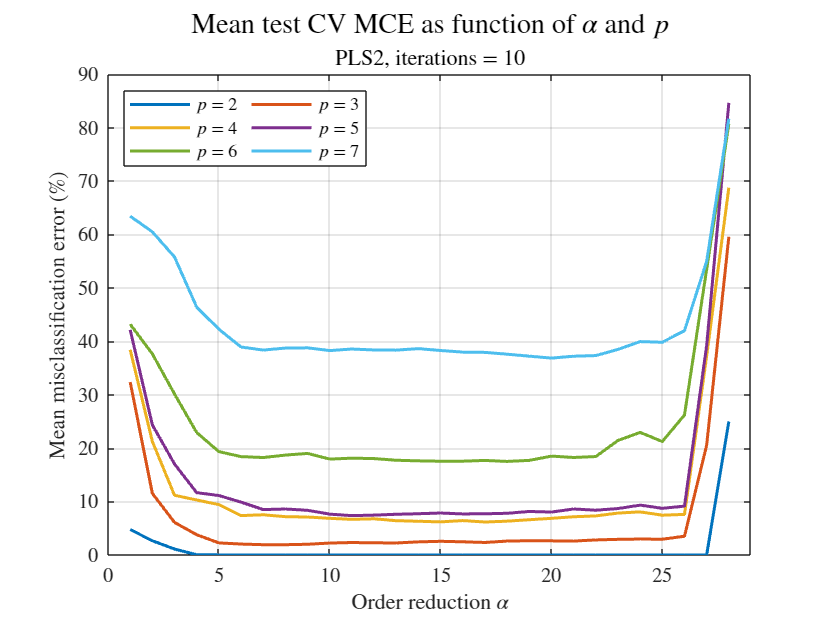

xlabel("Order reduction $\alpha$", 'Interpreter', 'latex');
ylabel("Mean misclassification error (\%)", 'Interpreter', 'latex');
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
leg = repmat("$p$ = ", 1, length(faultClasses)-1) + (2:length(faultClasses));
legend(leg, 'Interpreter', 'latex', 'Orientation', 'horizontal',...
    'Location', 'northwest', 'NumColumns', 2)
title("Mean test CV MCE as function of $\alpha$ and $p$", 'FontSize', 14, 'Interpreter', 'latex')
subtitle("PLS2, iterations = " + nIter, 'Interpreter', 'latex')

% PLS1
for nVar = 2:length(faultClasses)
    disp("p = " + nVar)
    subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
    X = subset{1:rowLimits(nVar), 1:28};
    Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
    mhat1 = PLS(X, Y, "Algorithm", "PLS1", "Trace", "off");
    mhat1 = mhat1.orderAnalysis(nIter);
    if nVar == 2
        figure
        plot(mhat1.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
        xlim([0 size(X, 2)+1])
    else
        hold on
        grid on
        plot(mhat1.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
    end
end

p = 2
p = 3
p = 4
p = 5
p = 6
p = 7


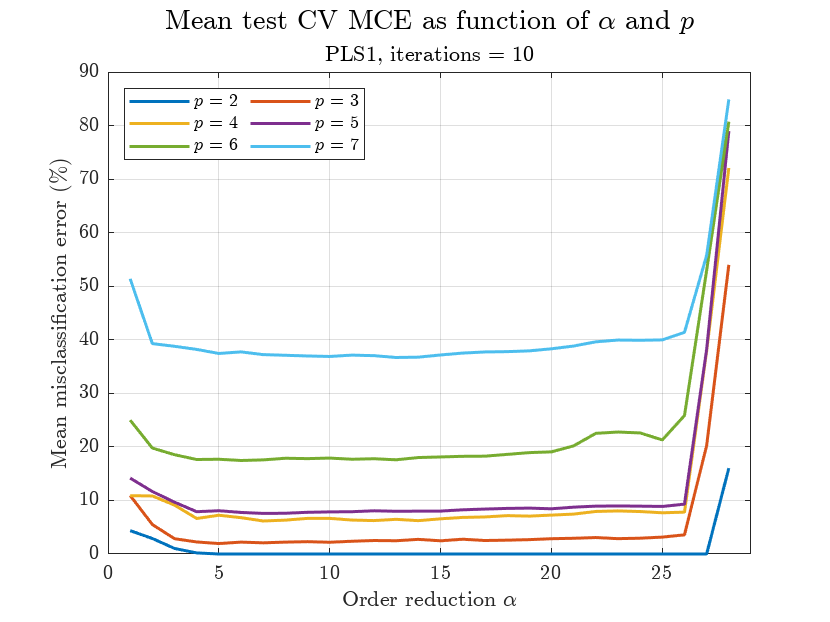

xlabel("Order reduction $\alpha$", 'Interpreter', 'latex');
ylabel("Mean misclassification error (\%)", 'Interpreter', 'latex');
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
leg = repmat("$p$ = ", 1, length(faultClasses)-1) + (2:length(faultClasses));
legend(leg, 'Interpreter', 'latex', 'Orientation', 'horizontal',...
    'Location', 'northwest', 'NumColumns', 2)
title("Mean test CV MCE as function of $\alpha$ and $p$", 'FontSize', 14, 'Interpreter', 'latex')
subtitle("PLS1, iterations = " + nIter, 'Interpreter', 'latex')

#### 3. Identification of the best order reduction through test CV MCE

nIter = 250;
nVar = 5;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};

% PLS2
model2 = PLS(X, Y, "Algorithm", "PLS2");

PLS configuration: 
- Algorithm: PLS2
- Normalization: true
- Maximum iterations: 1000
- Exit tolerance: 1e-10
- Num. of observations: 866
- Num. of output variables (Y): 5
- Num. of input variables (X): 28


model2 = model2.orderAnalysis(nIter);

% PLS1
model1 = PLS(X, Y, "Algorithm", "PLS1");

PLS configuration: 
- Algorithm: PLS1
- Normalization: true
- Maximum iterations: 1000
- Exit tolerance: 1e-10
- Num. of observations: 866
- Num. of output variables (Y): 5
- Num. of input variables (X): 28


model1 = model1.orderAnalysis(nIter);

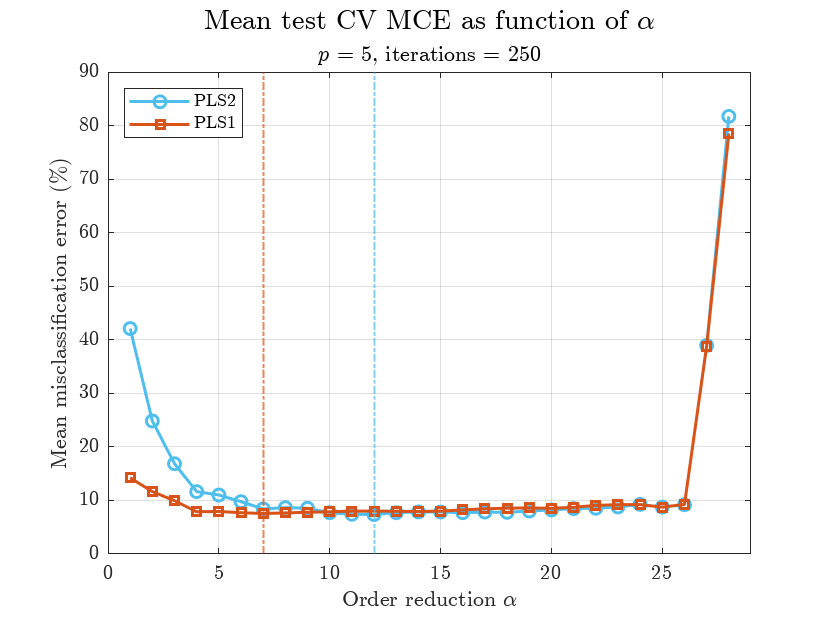

% results plotting
figure
plot(model2.orderRed.MCE_statistics.Avg*100, '-o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
plot(model1.orderRed.MCE_statistics.Avg*100, '-square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Mean misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northwest');
title("Mean test CV MCE as function of $\alpha$", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')

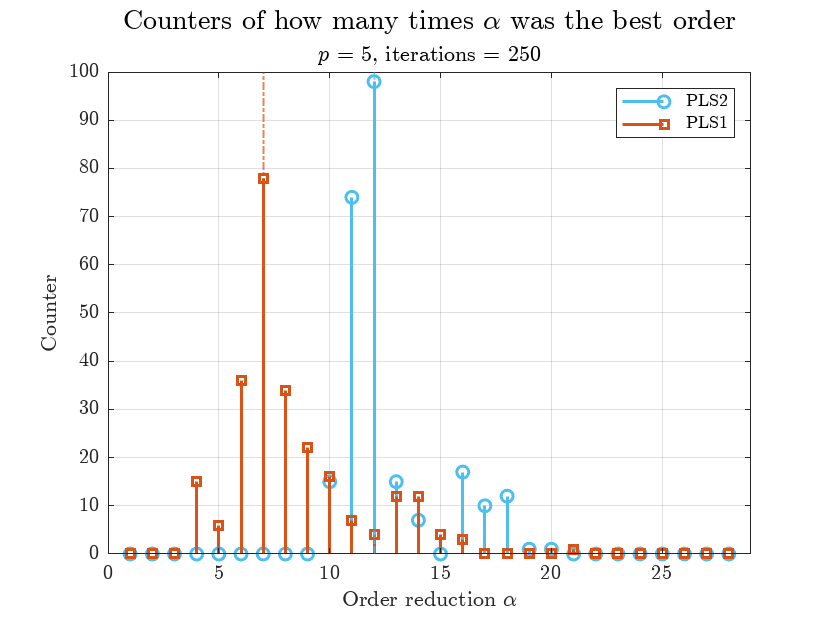

figure
stem(model2.orderRed.bestAlphaCounters.Counter, 'o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
stem(model1.orderRed.bestAlphaCounters.Counter, 'square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Counter', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northeast');
title("Counters of how many times $\alpha$ was the best order", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')

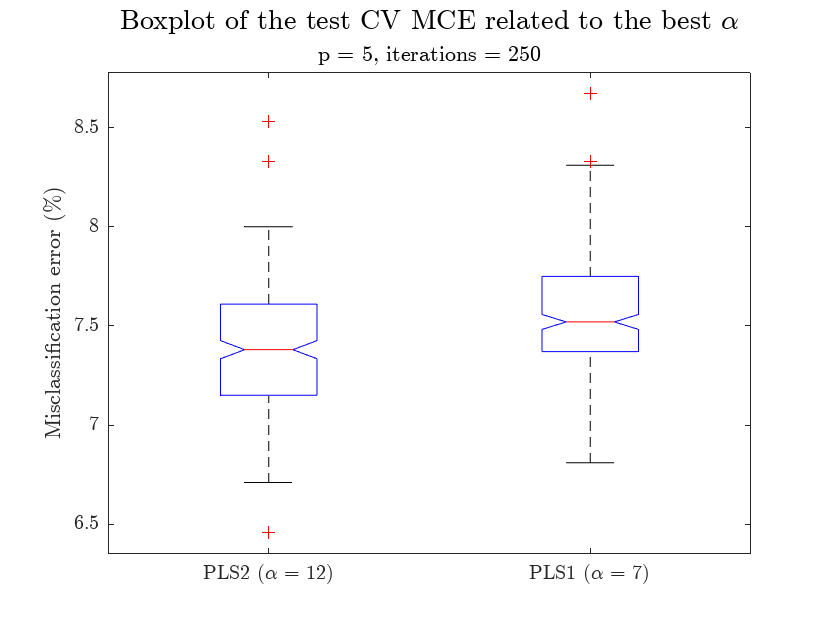

figure
bestAlphaMCE = array2table(zeros(nIter, 2));
bestAlphaMCE.Properties.VariableNames = ["PLS2", "PLS1"];
bestAlphaMCE.PLS2 = round(model2.orderRed.alphaMCE{model2.orderRed.bestAlpha, :}*100, 2)';
bestAlphaMCE.PLS1 = round(model1.orderRed.alphaMCE{model1.orderRed.bestAlpha, :}*100, 2)';
boxplot(bestAlphaMCE{:, :}, 'Labels', {'PLS2 ($\alpha$ = 12)', 'PLS1 ($\alpha$ = 7)'},...
    'Notch', 'on')
ylabel('Misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
title("Boxplot of the test CV MCE related to the best $\alpha$", 'Interpreter', 'latex',...
    'FontSize', 14)
subtitle("p = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')

#### **4. ****Performance analysis of the PLS algorithm, PLS2,  *****p =***** 5 and *****alpha***** = 12**

nVar = 5;
alpha = 12;
percent = .30;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};

% model estimation, validation and cross-validation
mhat = PLS(X, Y, "Algorithm", "PLS2");

PLS configuration: 
- Algorithm: PLS2
- Normalization: true
- Maximum iterations: 1000
- Exit tolerance: 1e-10
- Num. of observations: 866
- Num. of output variables (Y): 5
- Num. of input variables (X): 28


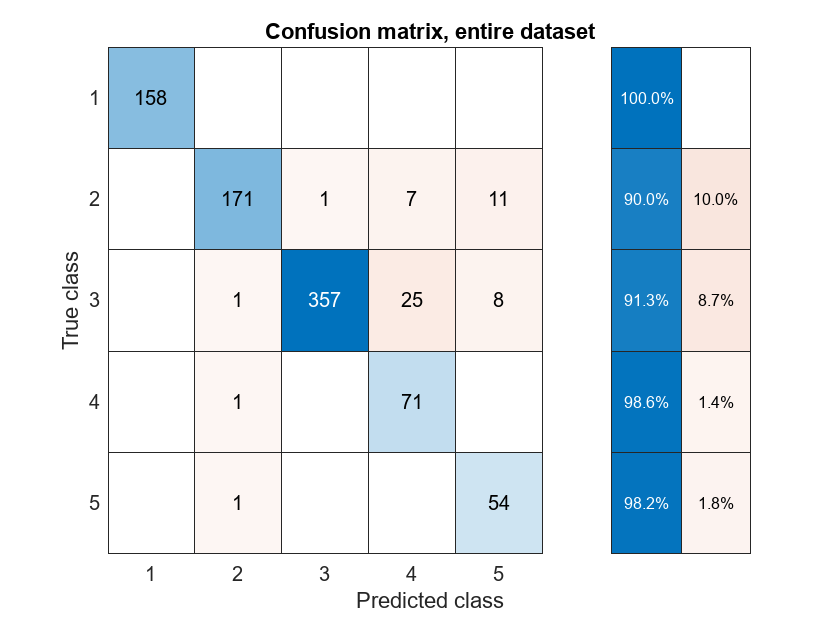

mhat = mhat.estimate(alpha);
mhat = mhat.predict;
mhat = mhat.crossval("Repeatable", "true");
mhat = mhat.validate(percent, "Repeatable", "true");

% confusion matrices
figure
g = confusionchart(mhat.confMatrix, 'RowSummary', 'row-normalized',...
    'Title', 'Confusion matrix, entire dataset');
g.XLabel = 'Predicted class';
g.YLabel = 'True class';

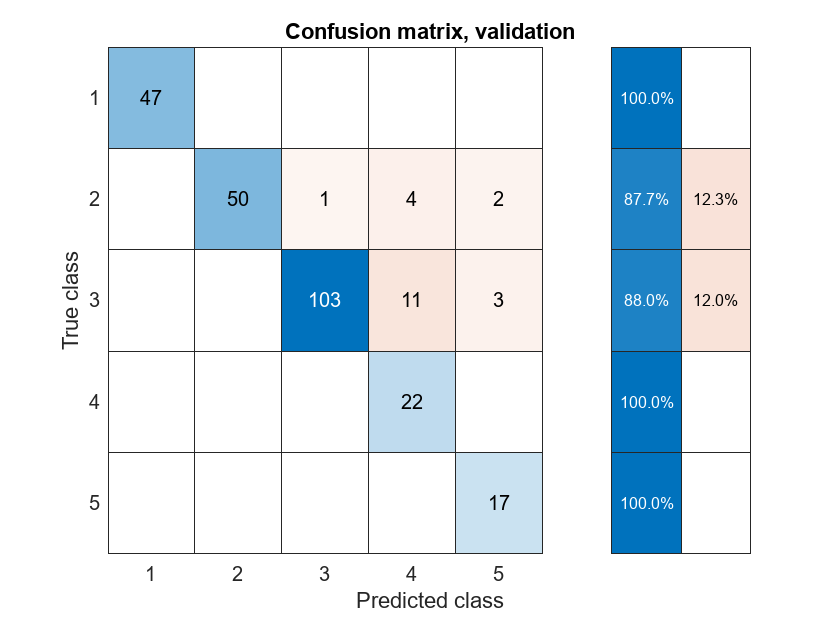

figure
g = confusionchart(mhat.TTV.confMatrix, 'RowSummary', 'row-normalized',...
    'Title', "Confusion matrix, validation");
g.XLabel = 'Predicted class';
g.YLabel = 'True class';

#### 5. Plot of T matrix with *alpha = *1, 2 and 3, PLS2, *p* = 2, 3, 4  and 5

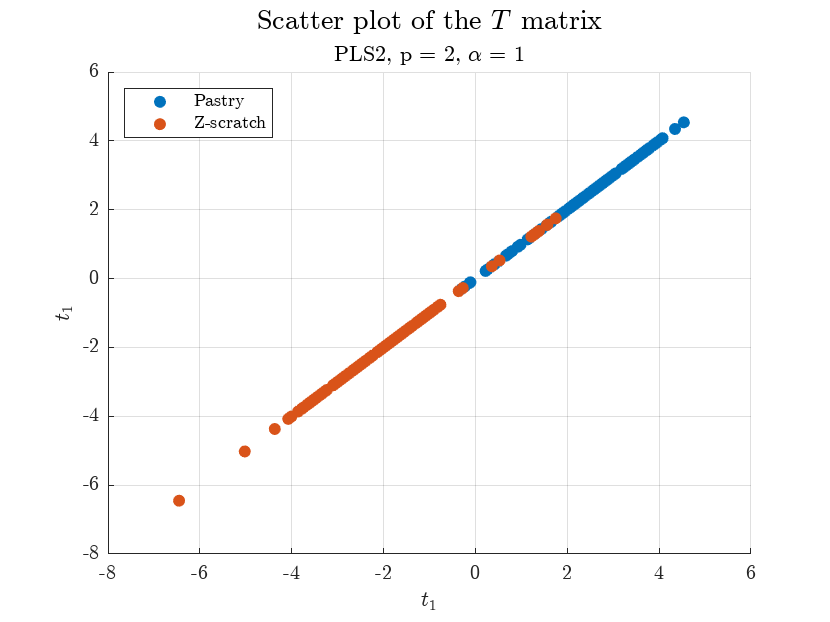

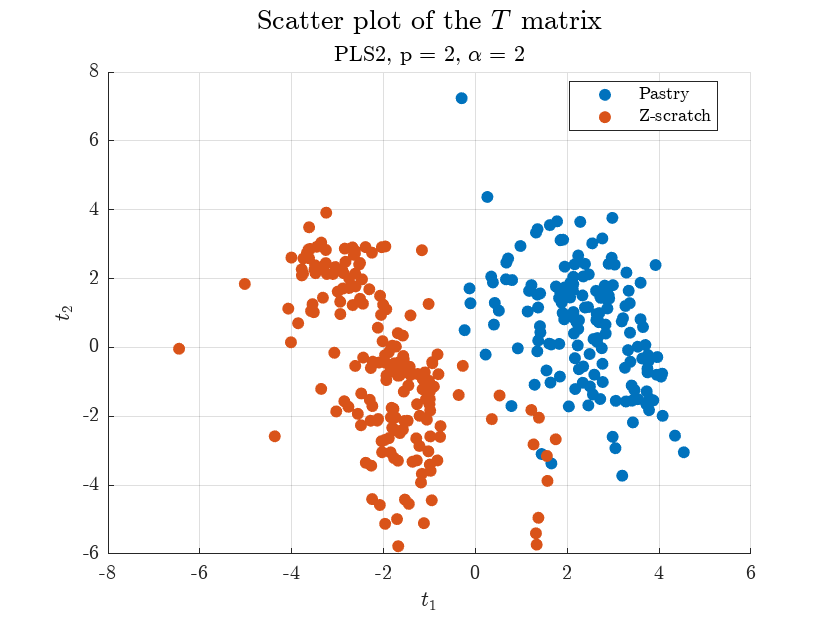

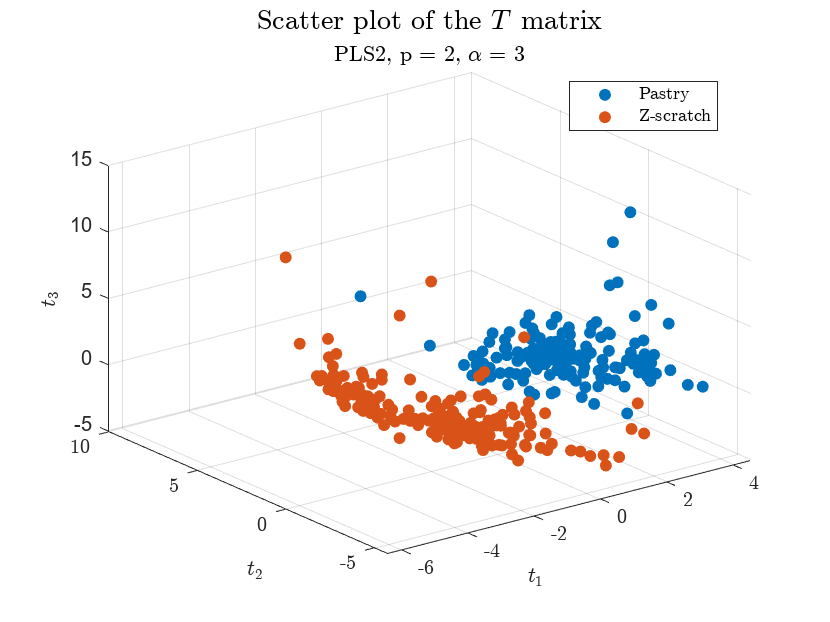

faultClassesNew = ["Pastry", "Z-scratch", "K-scratch", "Stains", "Dirtiness", "Bumps", "Other faults"];

% p = 2
nVar = 2;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
obj2 = PLS(X, Y, "Algorithm", "PLS2", "Trace", "off");
obj2 = obj2.plotScatter("ClassNames", faultClassesNew(1:nVar));

disp(obj2.scatterTable)

    Alpha    Pastry    Z-scratch    Avg 
    _____    ______    _________    ____

      1       2.53       5.79       4.31
      2       0.63       3.68        2.3
      3          0          0          0



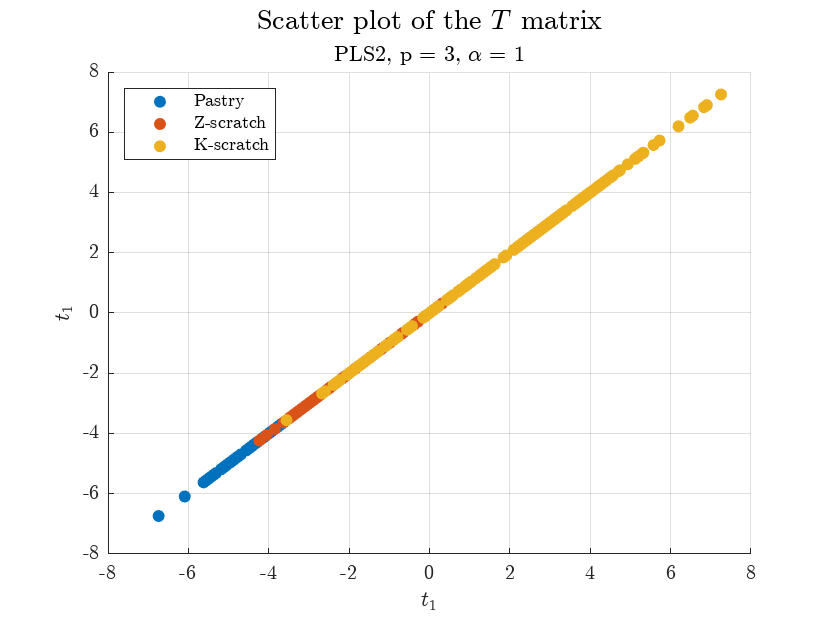

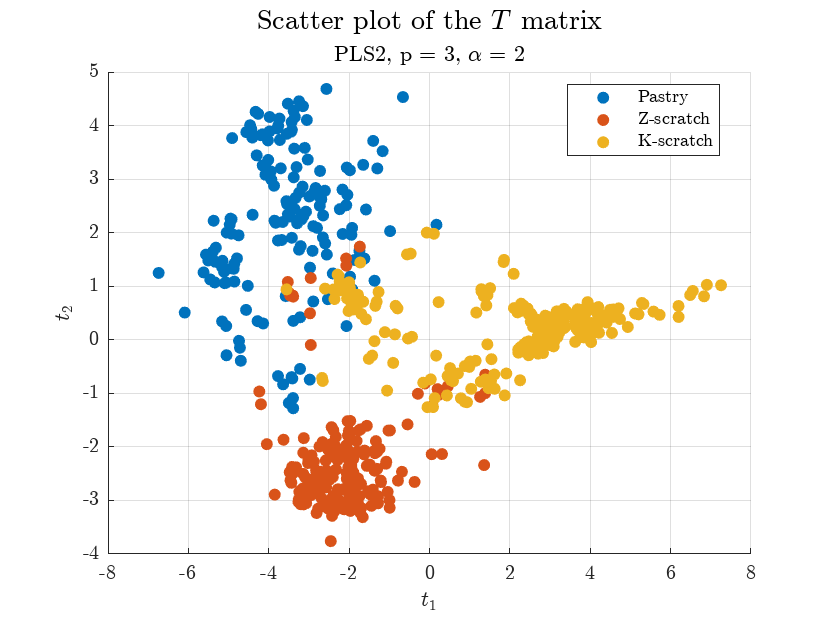

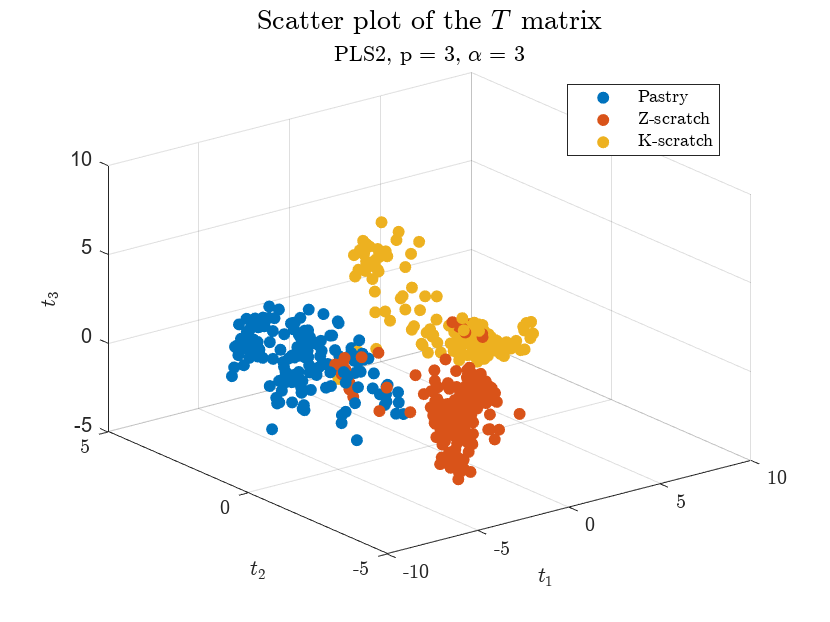

% p = 3
nVar = 3;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
obj3 = PLS(X, Y, "Algorithm", "PLS2", "Trace", "off");
obj3 = obj3.plotScatter("ClassNames", faultClassesNew(1:nVar));

disp(obj3.scatterTable)

    Alpha    Pastry    Z-scratch    K-scratch     Avg 
    _____    ______    _________    _________    _____

      1       0.63        100         11.76      32.07
      2       6.33       6.84         15.86       11.5
      3       6.33         10          3.32       5.68



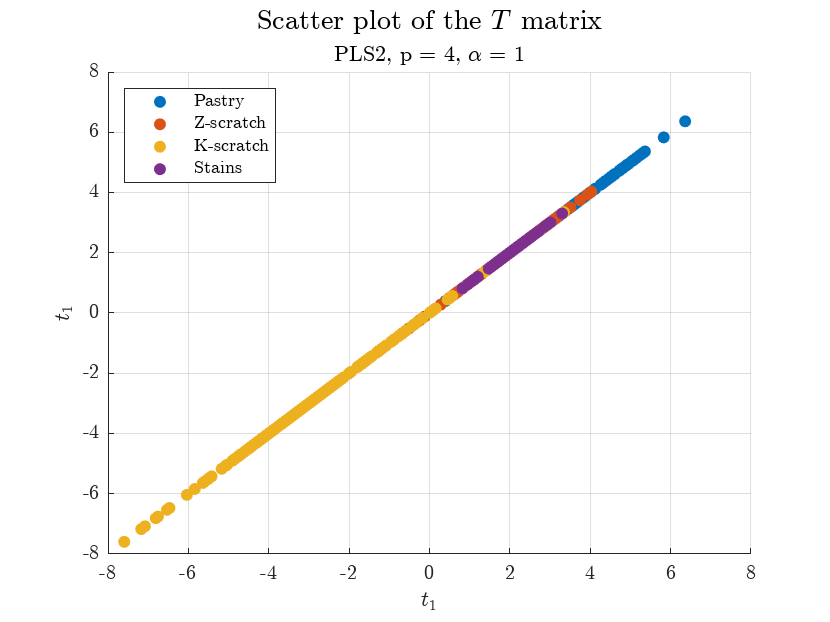

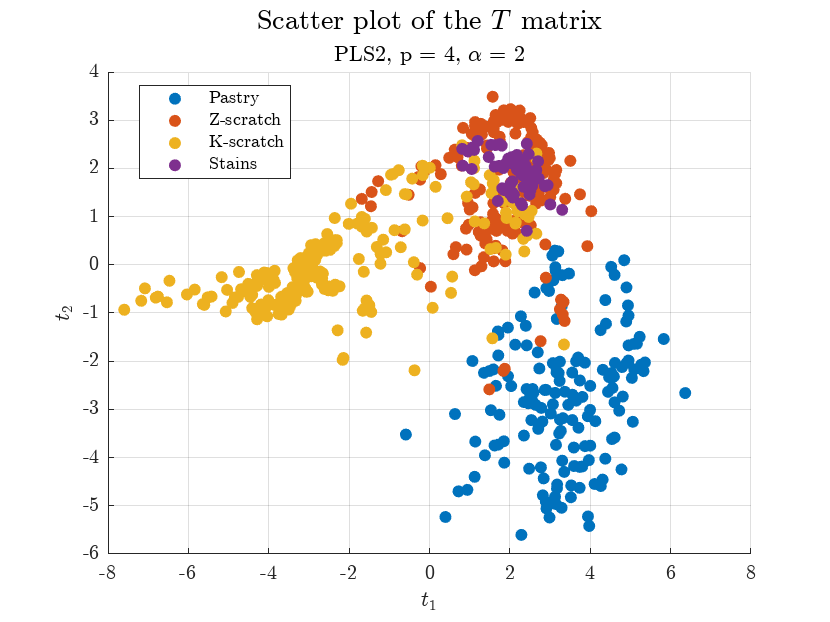

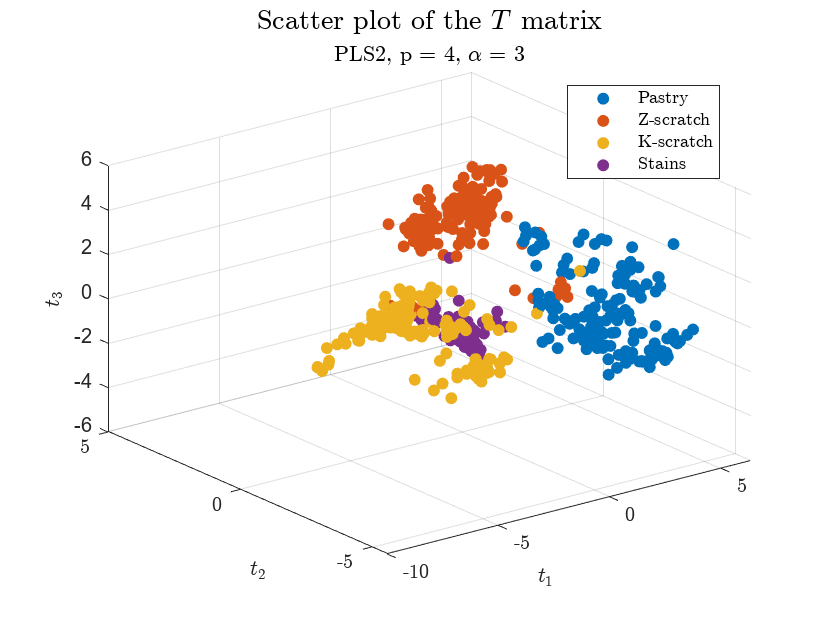

% p = 4
nVar = 4;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
obj4 = PLS(X, Y, "Algorithm", "PLS2", "Trace", "off");
obj4 = obj4.plotScatter("ClassNames", faultClassesNew(1:nVar));

disp(obj4.scatterTable)

    Alpha    Pastry    Z-scratch    K-scratch    Stains     Avg 
    _____    ______    _________    _________    ______    _____

      1       0.63         100        11.76        100      38.1
      2          0       11.05        14.58        100      18.5
      3        5.7          10        14.83       1.39     10.73



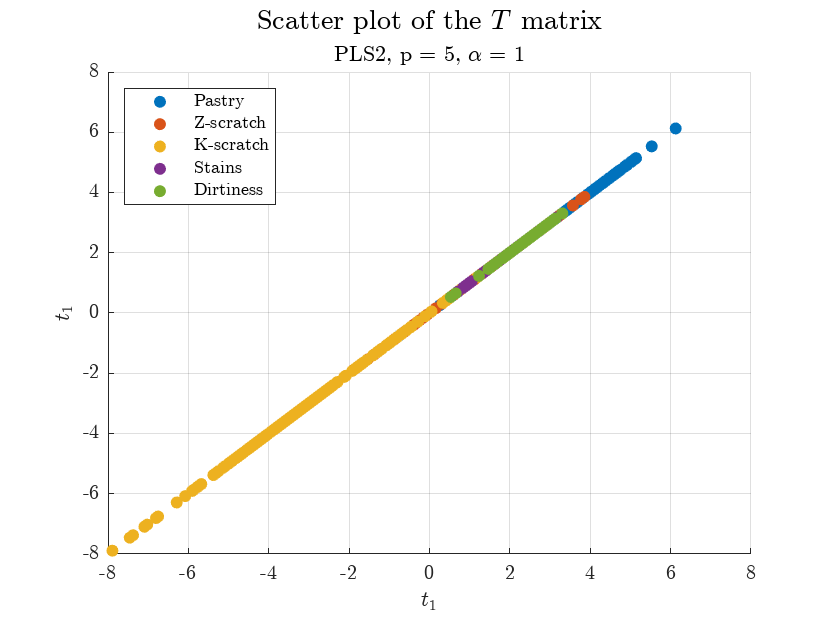

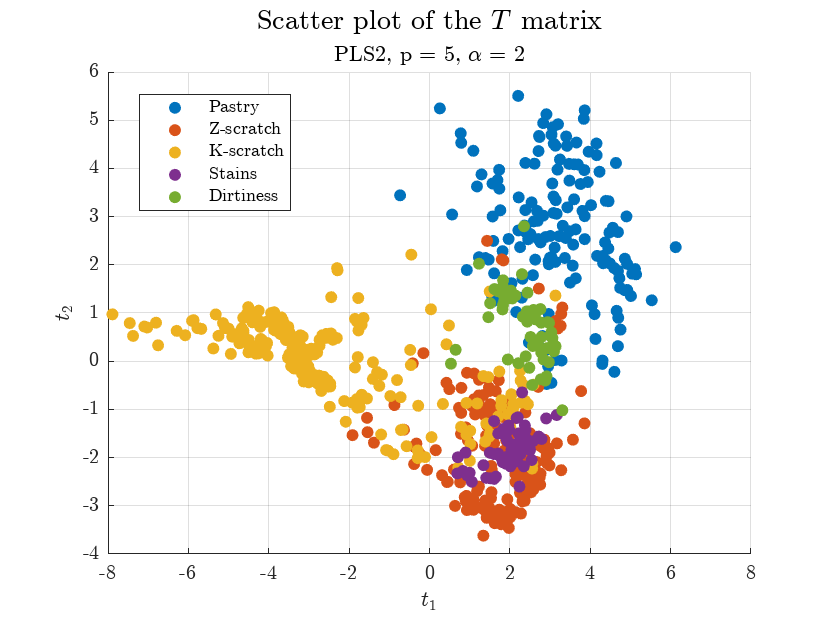

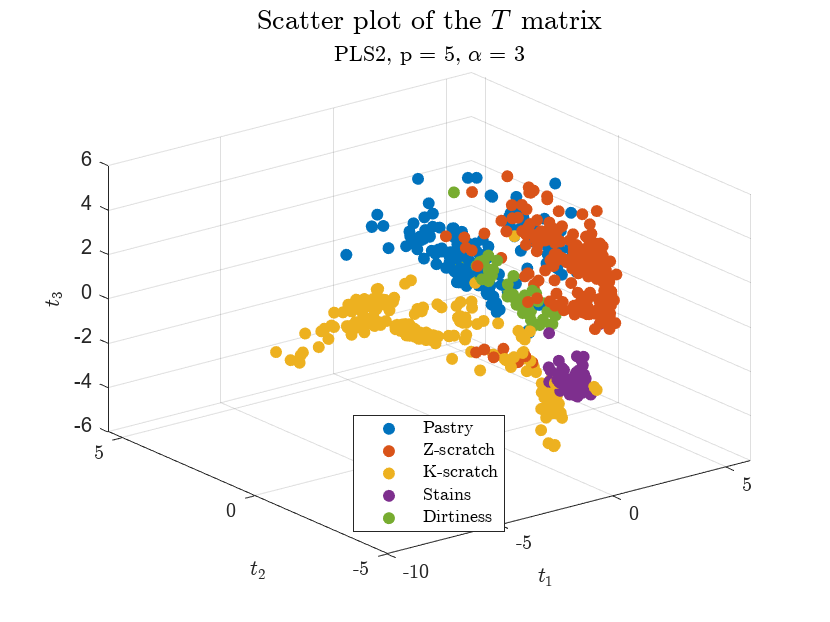

% p = 5
nVar = 5;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
obj5 = PLS(X, Y, "Algorithm", "PLS2", "Trace", "off");
obj5 = obj5.plotScatter("ClassNames", faultClassesNew(1:nVar));

disp(obj5.scatterTable)

    Alpha    Pastry    Z-scratch    K-scratch    Stains    Dirtiness     Avg 
    _____    ______    _________    _________    ______    _________    _____

      1       0.63        100         11.51        100        100       41.92
      2        1.9       8.42         14.58        100        100       23.44
      3       7.59         10         14.58       1.39        100       16.63

